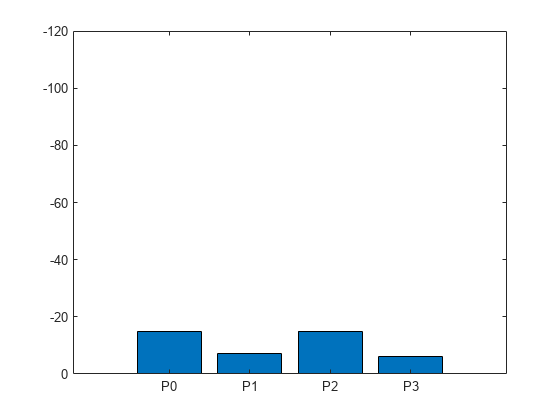

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in matlab.graphics.chart.primitive.bar.internal.updateTicks (line 6)
yTickData = get(hAx,yTickString);

Error in 

s = serialport("COM20", 115200);
s.configureTerminator("LF");

i = 0;
numReadouts = 100;
x = ["P0" "P1" "P2" "P3"];
a = [0 0 0 0];

figure(1)
while i < numReadouts*6
    line = readline(s);
    splitLine = split(line, ':');
    if splitLine(1) == "Central<-P subevent"
        slot = str2double(split(splitLine(4),','));
        rssi = split(splitLine(3),' ');
        switch slot(1)
            case 0
                a(1) = rssi(1);
            case 1
                a(2) = rssi(1);
            case 2
                a(3) = rssi(1);
            case 3
                a(4) = rssi(1);
        end
    end
    bar(a);
    axis ij
    ylim([-120 0])
    set(gca, 'XTickLabel', x)
    i = i + 1;
end


clear s